# **Preprocesamiento de datos de audio:**

clear all output
clc
warning('off','all')

## 1) Procesos ETL

% Definición del path con el dataset (en audios wav)
path_file = "dataset_wav\";

%%% Creación de la tabla data (con datos de cada audio del dataset)

% Uso de la función auxiliar tabladataset()
data = tabladataset();

% Dimensiones de la tabla data
l = height(data)

l = 611


% Añadir columnas a la tabla data
samplerate =     zeros(l,1);
frecmuestreo =   zeros(l,1);
sampledur =      zeros(l,1);
time =           zeros(l,1);
maxValue =       zeros(l,1);
minValue =       zeros(l,1);
meanValue =      zeros(l,1);
stdValue =       zeros(l,1);
speedup =        zeros(l,1);
volumegain =     zeros(l,1);
timeshift =      zeros(l,1);
variacion =      zeros(l,1);

t2 = table(samplerate,frecmuestreo,sampledur, time, maxValue, minValue, meanValue,stdValue);
data = [data,t2];

disp(data)

                                              nombre                                                bytes       grupo    formato                                                archivo                                                 samplerate    frecmuestreo    sampledur    time    maxValue    minValue    meanValue    stdValue
    __________________________________________________________________________________________    __________    _____    _______    ________________________________________________________________________________________________    __________    ____________    _________    ____    ______

disp(data.nombre(469))

    {'Roberto Carlos - La distancia'}



## **2) Conversión de audio a imagen característica**

iteraciones = 62

iteraciones = 62

muestra = 10

l = 611

i = 11

name = 1×1 cell array
    {'Albert Hammond - Ansiedad'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


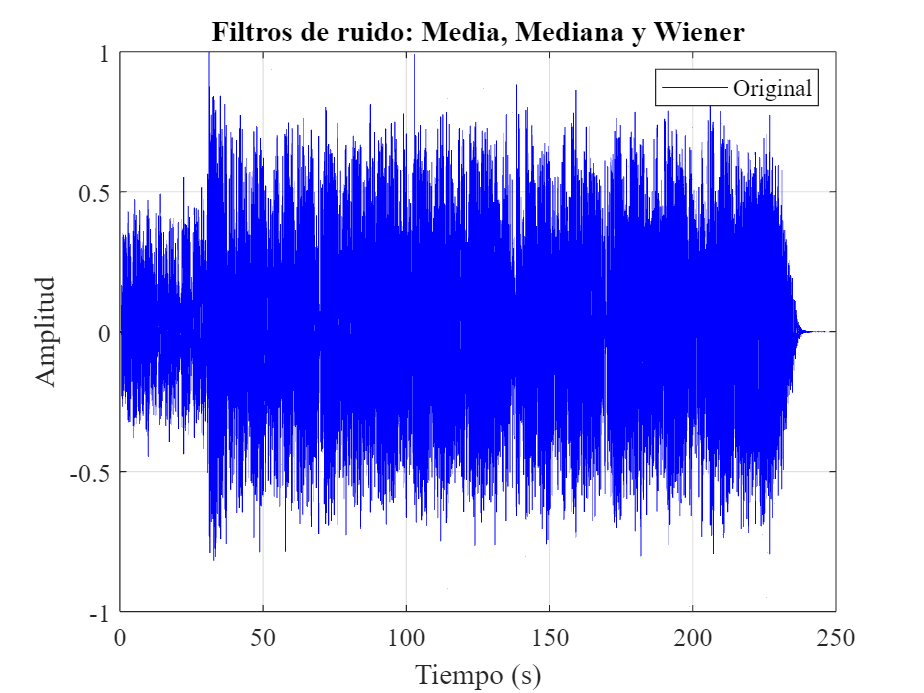

X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 12

name = 1×1 cell array
    {'Alejandro Sanz - Y si fuera ella'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


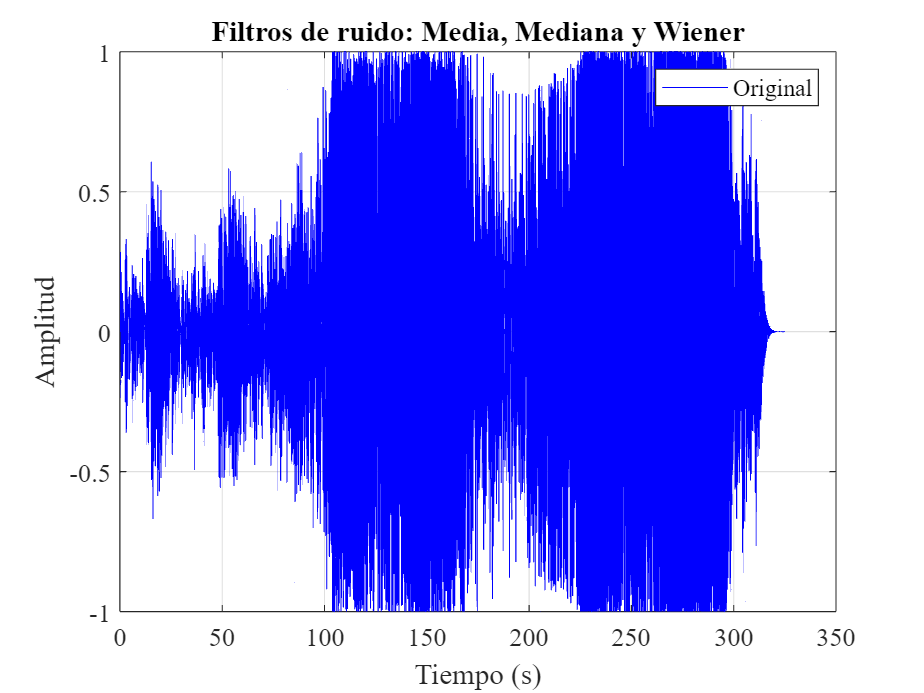

X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 13

name = 1×1 cell array
    {'Alejandro Sanz y David Bisbal - Y si fuera ella'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


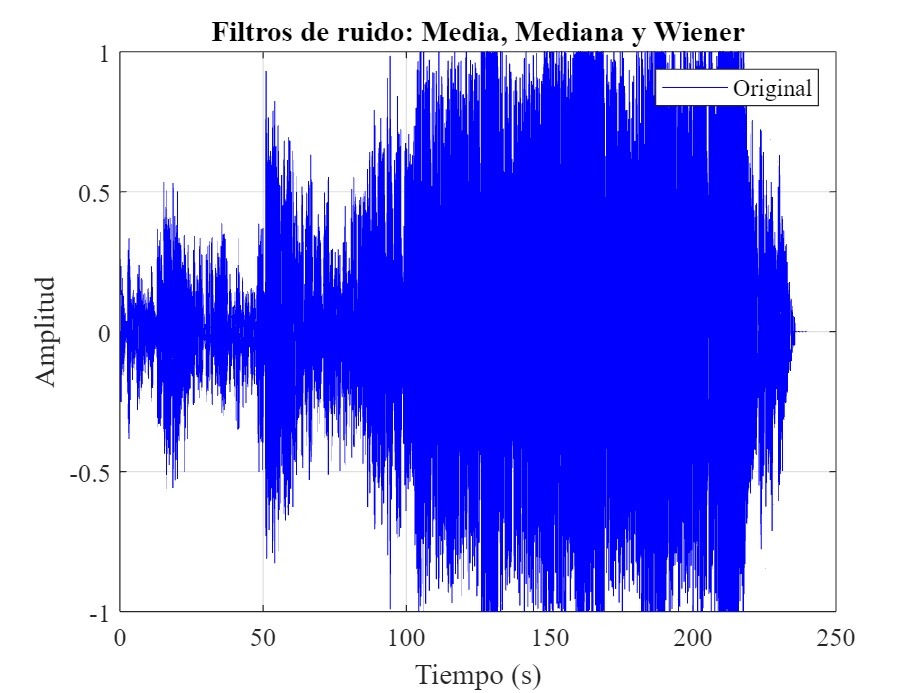

X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 14

name = 1×1 cell array
    {'All Green - Lets stay together'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


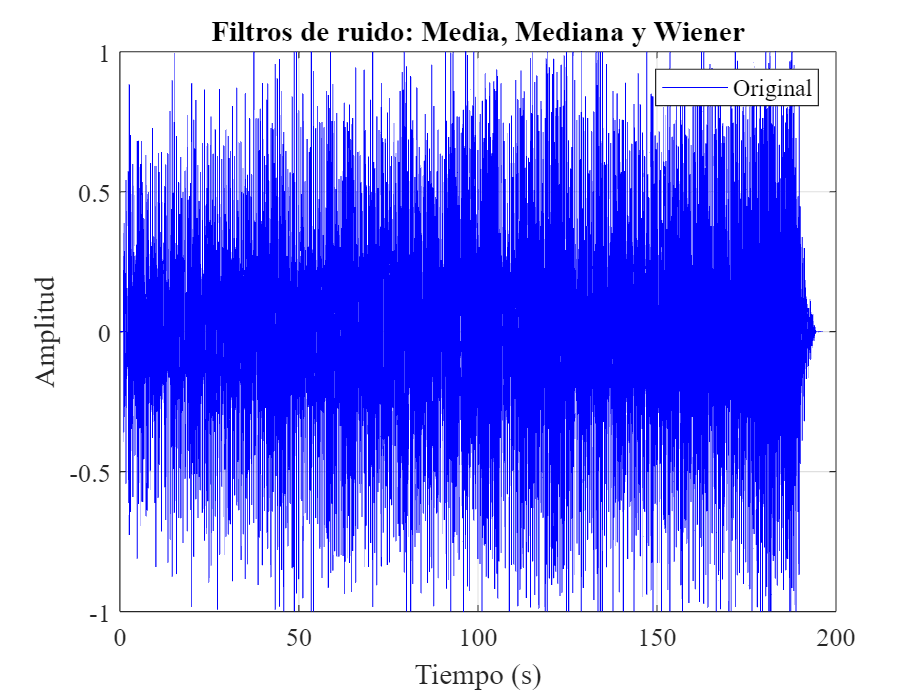

X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 15

name = 1×1 cell array
    {'Amaral - Te necesito'}


X_clean =     0.0059
    0.0058
    0.0057
    0.0057
    0.0056
    0.0055
    0.0054
    0.0053
    0.0052
    0.0051


X_clean =     0.0003
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006


X_clean =     0.0001
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002


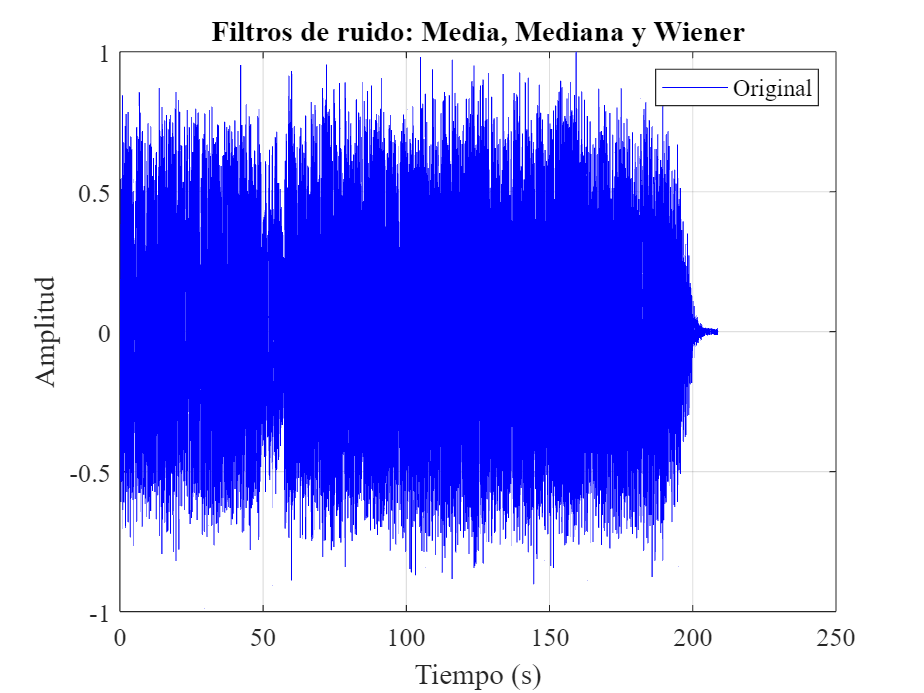

X_clean =     0.0001
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002


i = 16

name = 1×1 cell array
    {'Amaral - Toda la noche en la calle'}


X_clean =    -0.0093
   -0.0086
   -0.0077
   -0.0067
   -0.0058
   -0.0050
   -0.0042
   -0.0036
   -0.0033
   -0.0031


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


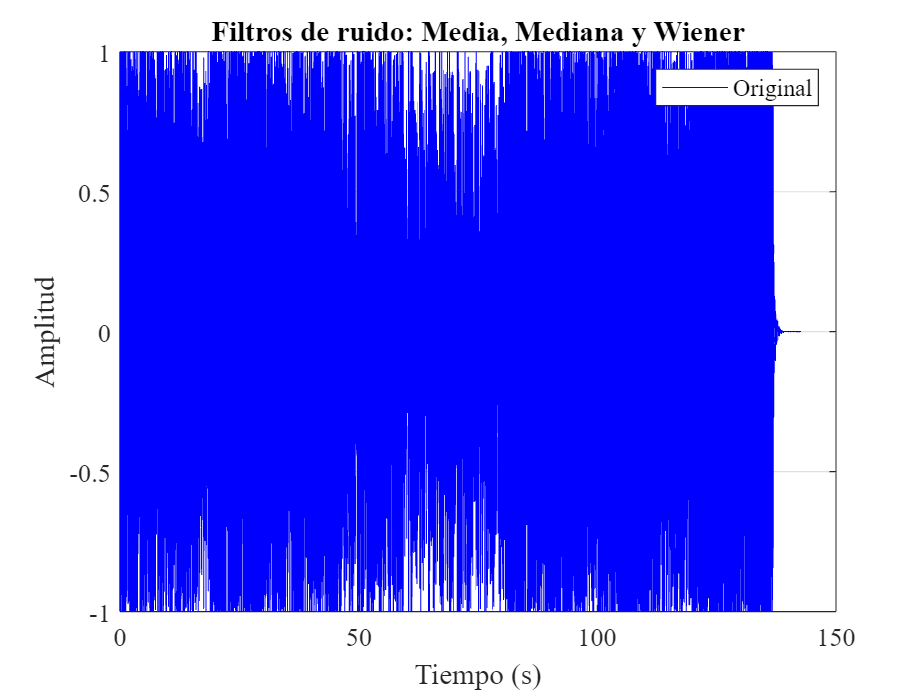

X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 17

name = 1×1 cell array
    {'Amaya Uranga - Palabras de amor'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


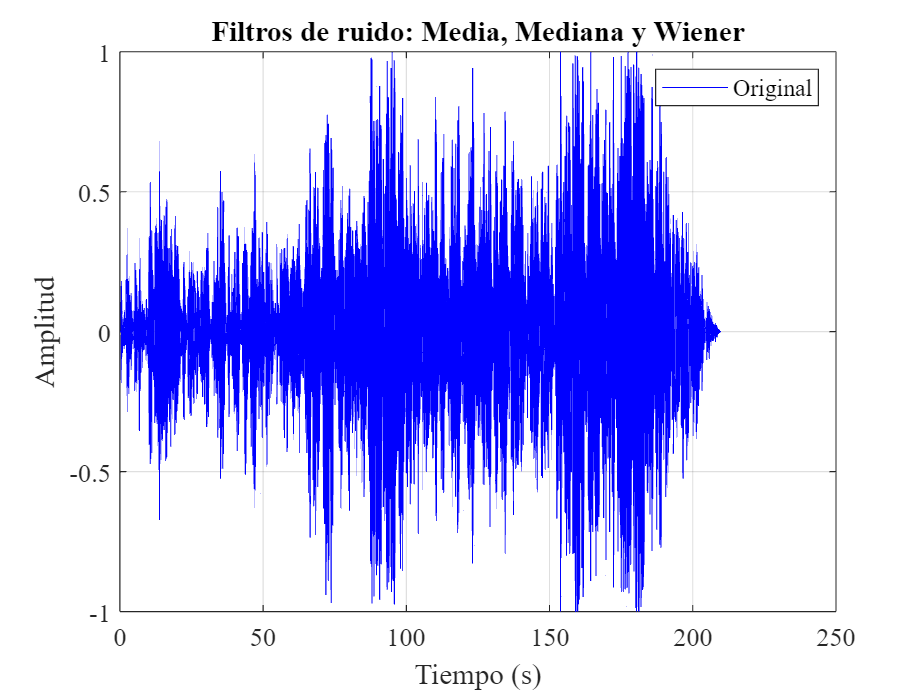

X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 18

name = 1×1 cell array
    {'Amber Taylor ft Josh Turner - Valerie'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


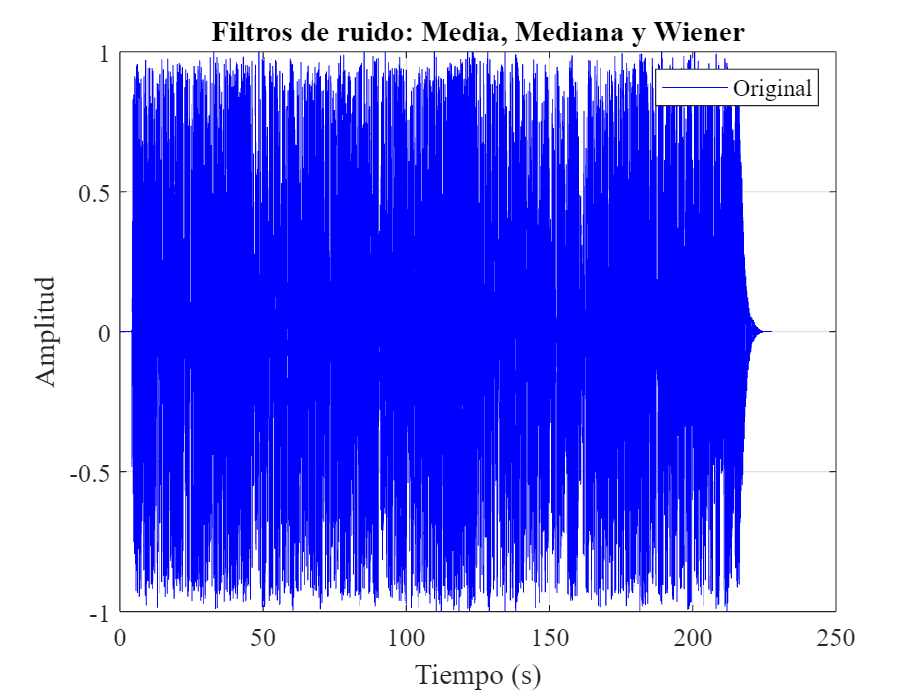

X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 19

name = 1×1 cell array
    {'America - A Horse With No Name'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


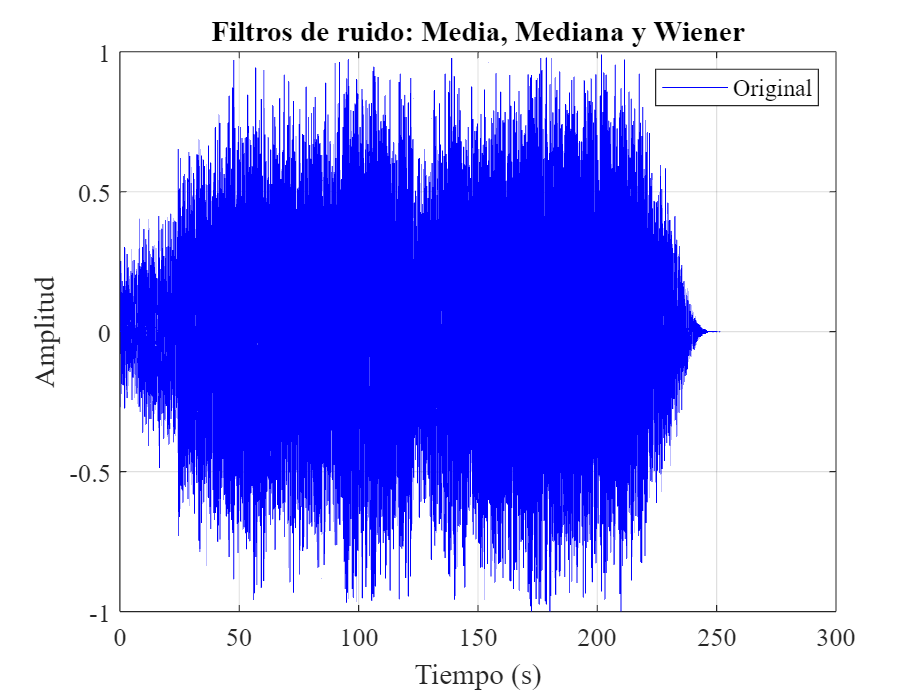

X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 20

name = 1×1 cell array
    {'America - A Horse With No Name (Riverside Remix)'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


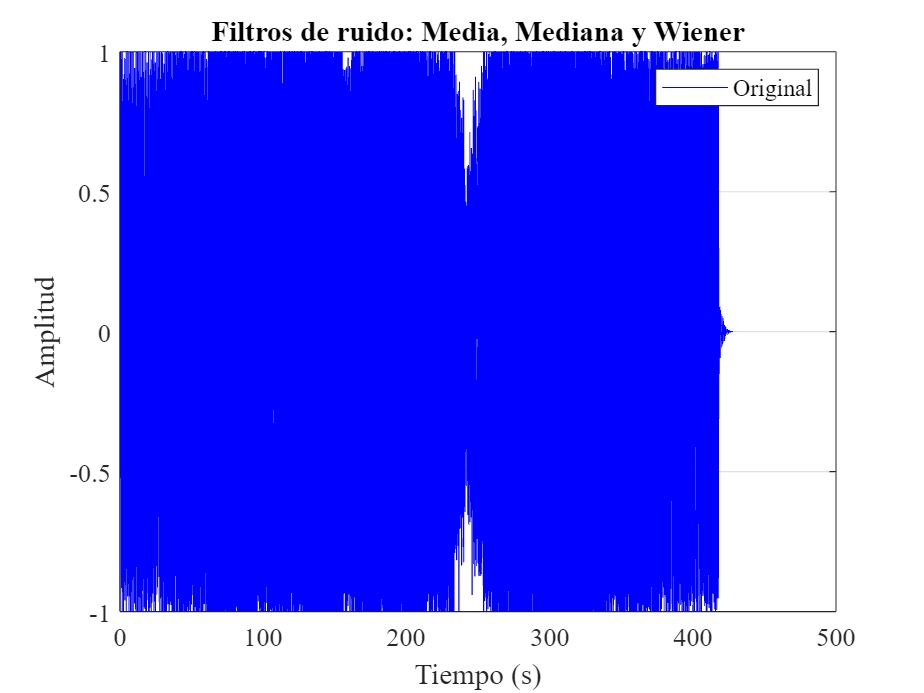

X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


muestra = 10

l = 611

i = 21

name = 1×1 cell array
    {'Amy Winehouse - Valerie'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 22

name = 1×1 cell array
    {'Amy Winehouse - Valerie (Mark Ronson)'}


X_clean =          0
         0
         0
         0
         0
         0
         0
         0
   -0.0000
   -0.0000


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 23

name = 1×1 cell array
    {'Ana Belen - A la sombra de un leon'}


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 10791870×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 10791870×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 24

name = 1×1 cell array
    {'Ana Belén - El hombre del piano'}


X_clean = 13245168×1
1.0e+00 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


X_clean = 13245168×1
1.0e+00 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


X_clean = 13245168×1
1.0e+00 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


X_clean = 13245168×1
1.0e+00 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


i = 25

name = 1×1 cell array
    {'Ana Torroja,- Aire (Festival de Vina)'}


X_clean = 12489456×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 12489456×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 12489456×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 12489456×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 26

name = 1×1 cell array
    {'Andy Williams (BSO Bridget Jones) - Cant take my eyes off you'}


X_clean = 8361840×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 8361840×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 8361840×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 8361840×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 27

name = 1×1 cell array
    {'Angelina Jordan - Billie Jean (jazzy Michael Jackson cover)'}


X_clean = 11725680×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 11725680×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 11725680×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 11725680×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 28

name = 1×1 cell array
    {'Angelina Jordan - House of the rising sun'}


X_clean = 5531376×1
1.0e+00 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


X_clean = 5531376×1
1.0e+00 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


X_clean = 5531376×1
1.0e+00 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


X_clean = 5531376×1
1.0e+00 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


i = 29

name = 1×1 cell array
    {'Annie Lennox - A whiter shade of pale'}


X_clean = 12822384×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 12822384×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 12822384×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 12822384×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


i = 30

name = 1×1 cell array
    {'Annie Lennox - Hallelujah'}


X_clean = 10708464×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 10708464×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 10708464×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


X_clean = 10708464×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for k = 1:2
    muestra = 10
    path_file = "dataset_wav\";
    data = tabladataset();
    l = height(data)

    for h = 1:muestra
        i = k*10 + h
        
        if (i<1)
            continue
        end
        % Parar el bucle
        if i == height(data)
            break
        end
        % Lectura del audio
        arch = data.archivo(i);
        audio_file = strcat(path_file,arch);
        [X,fs] = audioread(audio_file);
    
        % Especificar el uso de un solo canal del audio
        X = X(:,1);
    
        % Creación de carpetas para la organización del dataset
        name = data.nombre(i)
        group = string(data.grupo(i));
        name = string(name);
        
        if not(isfolder(name))
            mkdir('features',name);
        end
        
        if not(isfolder(group))
            mkdir('pair',group);
        end
            
        % Definición de los path del dataset, para guardar pares y las características de cada elemento del dataset
        folderpath1 = "C:\2\TFG\TFG programa\features\";
        featurepath = strcat(folderpath1,name);
    
        folderpath2 = "C:\2\TFG\TFG programa\pair\";
        pairpath = strcat(folderpath2,group);
        
        %%% Extracción de las características físicas del audio
        
        % Duración de un sample
        sample_duration = 1/fs;
        
        % Número de samples
        N = length(X);
        t = (0:N-1)/fs;
    
        % Duración del audio:
        duracion = sample_duration*length(X);
    
        % Relleno de las columnas añadidas previamente a la tabla data
        data.samplerate(i) = fs;
        data.frecmuestreo(i)= fs/2;
        data.sampledur(i)= sample_duration;
        data.time(i)= duracion;
    
    
        %%% Limpieza del audio
    
        % Uso de la función auxiliar cleaner para la eliminación de ruido
        X_clean = cleaner(X,t)
    
        %%% Extracción de características
    
        % Información estadística del audio
        data.maxValue(i) = max(X_clean);
        data.minValue(i) = min(X_clean);
        data.meanValue(i) = mean(X_clean);
        data.stdValue(i) = std(X_clean);
    
        % Extracción de características con la función auxiliar
        % feature_extraction()
        feature_extraction(X_clean,t,fs,N,featurepath);
        
        % Generación de la imagen característica con la función
        % auxiliar feature_concat()
        feature_concat(data,i,featurepath,pairpath,0);
    
        % Aumentación de datos con la función data_augmentation
        data_augmentation(X,fs,data,i,pairpath)

        clc
    end
end